# Initialize

figure;
img_path = "images/";

img_multiBlocks = imread(img_path + 'minecraft_blocks.jpg');
img_circles = imread(img_path + 'circles.jpg');

%subplot(1,2,1); imshow(img_multiBlocks)
%subplot(1,2,2); imshow(img_circles)

## Image Segmentation

figure; %('Position', [0 0 350 600]);
nr_of_techniques = 4;

% Needs to be grayscale to binarize
img_gray = rgb2gray(img_multiBlocks);

subplot(nr_of_techniques,2,1); imshow(img_multiBlocks);
%subplot(nr_of_techniques,2,2); imshow(img_gray);

### Otsu's Method

#### Global Threshold

globalThresh = graythresh(img_gray);
img_bw_global = imbinarize(img_gray, globalThresh);

subplot(nr_of_techniques,2,3); imshow(img_bw_global); ylabel("Global");

#### Global Histogram Threshold

num_of_bins = 16;
[counts,x] = imhist(img_gray, num_of_bins);
globalThresh_hist = otsuthresh(counts);
% Binarize based on global threshold
img_bw_global_hist = imbinarize(img_gray, globalThresh_hist);

subplot(nr_of_techniques,2,5); imshow(img_bw_global_hist); ylabel("Global Hist")
subplot(nr_of_techniques,2,6); stem(x,counts); title("Histogram");

#### Multilevel Threshold 

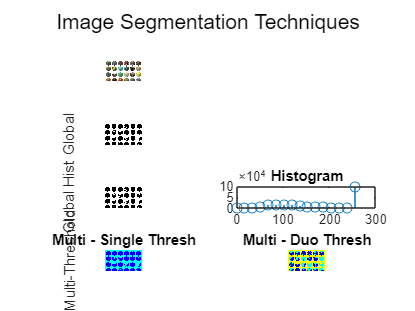

% 1 Thresh - Separate into 2 regions
levelThresh_single = multithresh(img_gray);
img_bw_multi_single = imquantize(img_gray, levelThresh_single);

% 2 Thresh - Separate into 3 regions
levelThresh_duo = multithresh(img_gray,2);
img_bw_multi_duo = imquantize(img_gray, levelThresh_duo);

subplot(nr_of_techniques,2,7); imshow(label2rgb(img_bw_multi_single)); ylabel("Multi-Threshold"); title("Multi - Single Thresh");
subplot(nr_of_techniques,2,8); imshow(label2rgb(img_bw_multi_duo)); title("Multi - Duo Thresh");

sgtitle("Image Segmentation Techniques");

### Snakes (Region Growing Technique)

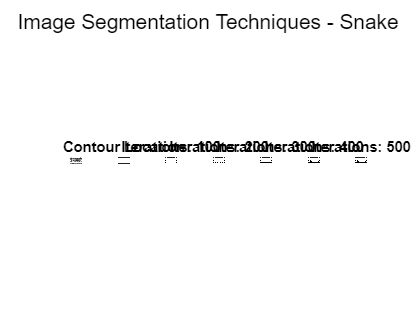

figure;
mask_contour_region = zeros(size(img_gray));
mask_contour_region(25:end-25,25:end-25) = 1;

nr_of_iterations = 100;
nr_of_loops = 5;
nr_of_cols = nr_of_loops + 2;

subplot(1, nr_of_cols, 1); imshow(img_gray);
subplot(1, nr_of_cols, 2); imshow(mask_contour_region); title('Contour Location');

j = 3;
for i=1:nr_of_loops
    subplot(1, nr_of_cols, j); imshow(activecontour(img_gray, mask_contour_region, nr_of_iterations));
    title("Iterations: " + nr_of_iterations);
    
    j = j + 1;
    nr_of_iterations = nr_of_iterations + 100;
end

sgtitle("Image Segmentation Techniques - Snake");

## Object Analysis

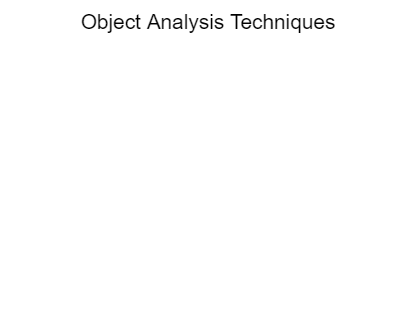

%figure;
%sgtitle("Object Analysis Techniques");